clear all; close all;

## Constants

epsilon_0 = 8.85e-12;

fpoints = 75;

tstart = 0;
tstop = 5e-6;
tpoints = 500;
t = linspace(tstart, tstop, tpoints);
t = reshape(t, [length(t), 1]);

num_of_sections = 8;
num_of_combinations = 2^num_of_sections;

l = 4e-6;
input_matrix = create_input_matrix(num_of_sections);

## Main Code Setup

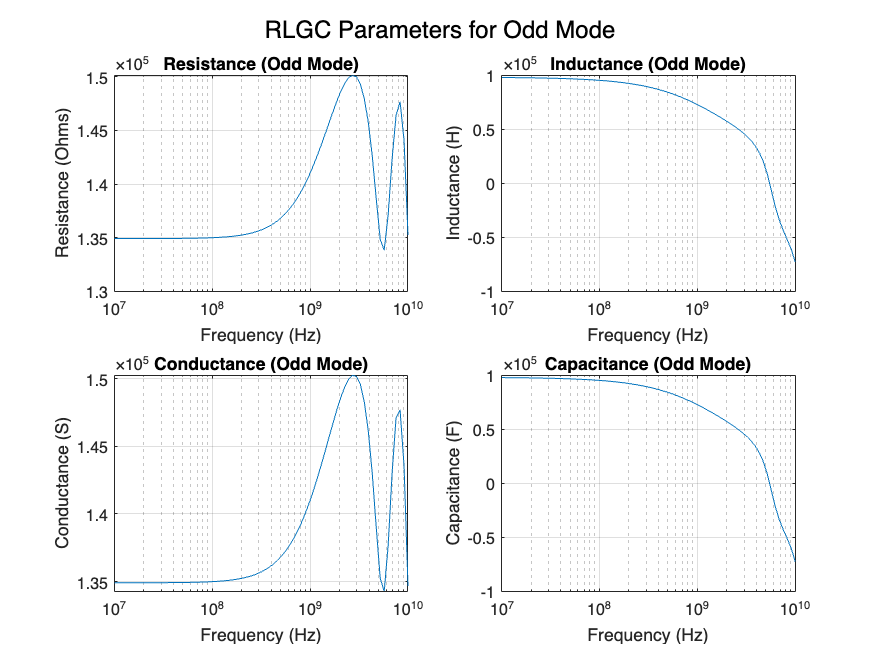

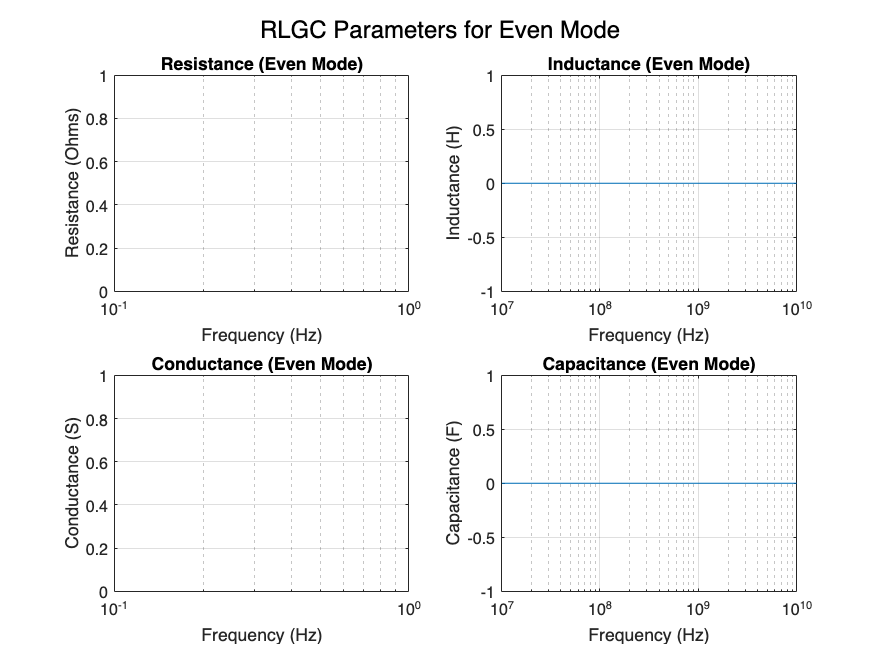

[f, Z0_odd, gamma_odd, Z0_even, gamma_even, R_odd, L_odd, G_odd, C_odd, R_even, L_even, G_even, C_even] = readFromCSV('RLGCK.csv');

% Reassign reshaped f
f = reshape(f, [1, fpoints]);

% Reassign reshaped Z0_odd
Z0_odd = reshape(Z0_odd', [1, fpoints]);

% Reassign reshaped gamma_odd
gamma_odd = reshape(gamma_odd', [1, fpoints]);

% Repeat the same process for the remaining variables...

% Reassign reshaped Z0_even
Z0_even = reshape(Z0_even', [1, fpoints]);

% Reassign reshaped gamma_even
gamma_even = reshape(gamma_even', [1, fpoints]);

% Reassign reshaped R_odd
R_odd = reshape(R_odd', [1, fpoints]);

% Reassign reshaped L_odd
L_odd = reshape(L_odd', [1, fpoints]);

% Reassign reshaped G_odd
G_odd = reshape(G_odd', [1, fpoints]);

% Reassign reshaped C_odd
C_odd = reshape(C_odd', [1, fpoints]);

% Repeat the same process for the remaining variables...

% Reassign reshaped R_even
R_even = reshape(R_even', [1, fpoints]);

% Reassign reshaped L_even
L_even = reshape(L_even', [1, fpoints]);

% Reassign reshaped G_even
G_even = reshape(G_even', [1, fpoints]);

% Reassign reshaped C_even
C_even = reshape(C_even', [1, fpoints]);


C_shunt = 10*max(C_odd);
plotRLGC(f, R_odd, L_odd, G_odd, C_odd, R_even, L_even, G_even, C_even);



[Cm, Ca, Gm, Ga] = odd_even_2_m_a(C_odd, C_even, G_odd, G_even);

[Z0o_off, Z0o_on, Z0e_off, Z0e_on, gamma_o_off, gamma_o_on, gamma_e_off, gamma_e_on, theta_o_off, theta_o_on, theta_e_off, theta_e_on] = Z0_even_odd_on_off(f, L_odd, L_even, Cm, Ca, C_shunt, Gm, Ga, R_odd, R_even);

## All possible ABCD matrices

[Ao_off, Ae_off, Ao_on, Ae_on] = create_on_off_A_matrices(gamma_o_off, gamma_e_off, Z0o_off, Z0e_off, gamma_o_on, gamma_e_on, Z0o_on, Z0e_on, l);


## Plot odd and even input impedances

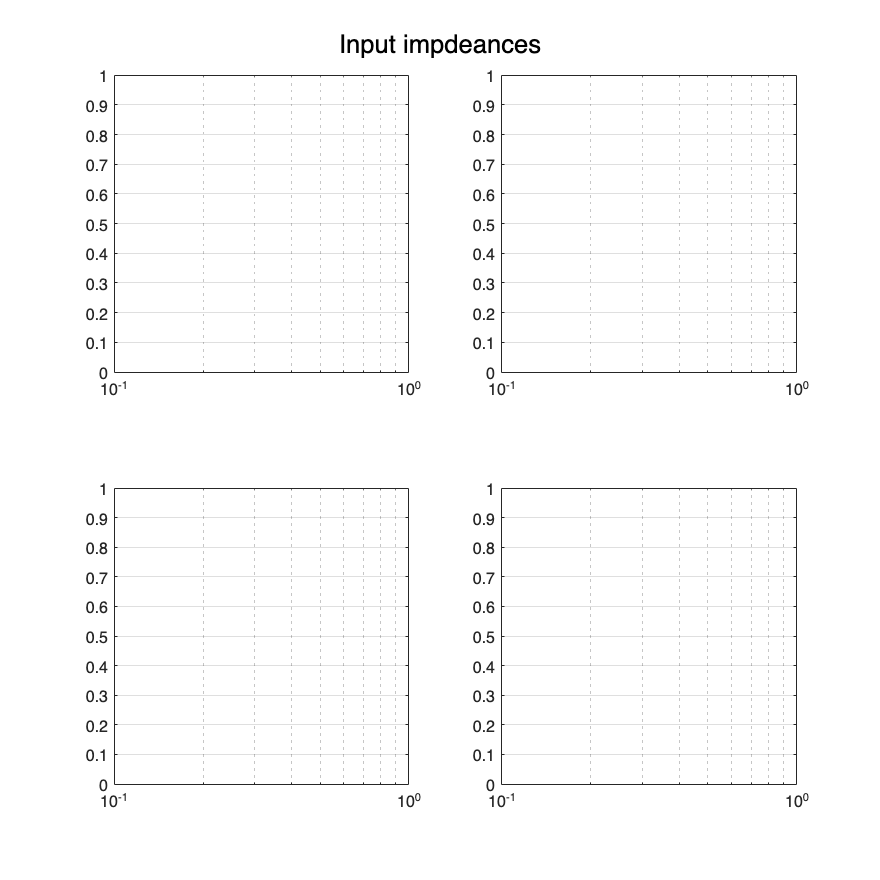

[Zin_o_off, Zin_o_on, Zin_e_off, Zin_e_on] = find_all_Zins(Z0o_off, Z0o_on, Z0e_off, Z0e_on, gamma_o_off, gamma_o_on, gamma_e_off, gamma_e_on, l, 50);
plot_possible_Zins(f, Zin_o_off, Zin_o_on, Zin_e_off, Zin_e_on);

## On and Off S parameters

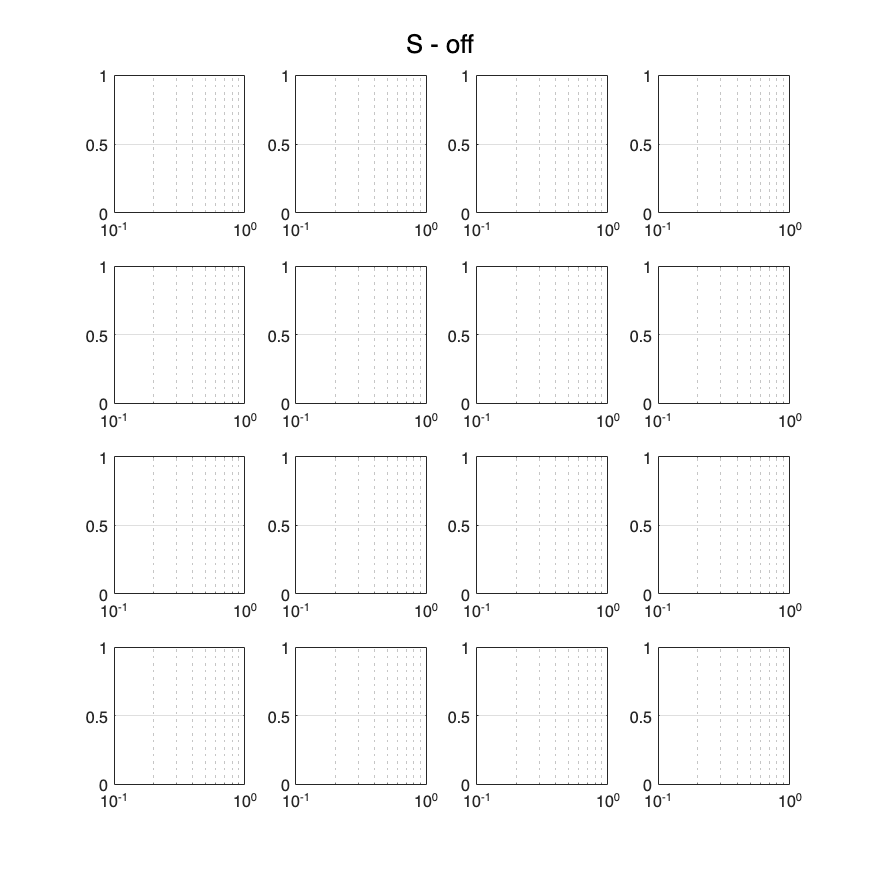

Zin = 50*ones(1, length(f));
S_off = a2sw(Ao_off, Ae_off, Zin, Zin, Zin, Zin);
S_on = a2sw(Ao_on, Ae_on, Zin, Zin, Zin, Zin);
plot_full_S_params(f, S_off, 'S - off');

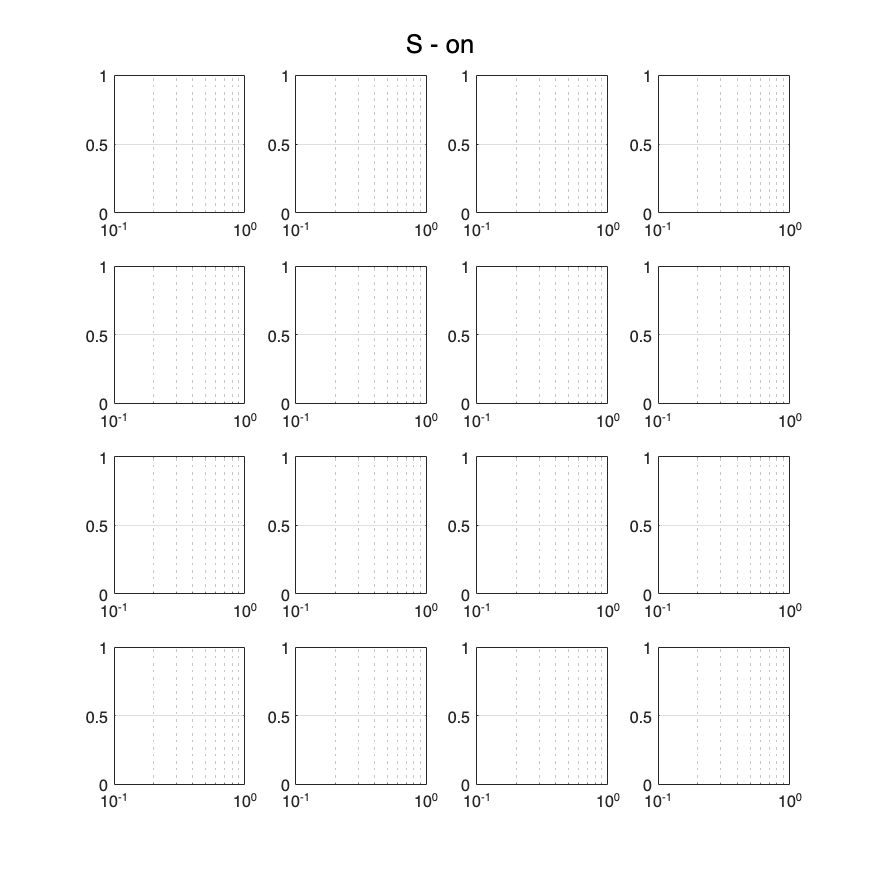

plot_full_S_params(f, S_on, 'S - on');



% Initialize a cell array to store the identity matrices
identity_matrices = cell(1, fpoints);
% Create identity matrices and store them in the cell array
for i = 1:fpoints
    identity_matrices{i} = eye(4);
end

% Create a cell array to store S matrices
S_cell_array = cell(num_of_combinations, 1);

for index = 1:1:num_of_combinations
    S = cat(3, identity_matrices{:}); % initialse S matrix
    for j = 1:num_of_sections % iterate aross sections
        if (input_matrix(index, j) == 1)
            [Z01_odd, Z02_odd, Z03_odd, Z04_odd] = find_Zin_for_curr_section(num_of_sections, j, find_Zc(f, R_odd, L_odd, G_odd, C_odd+C_shunt), gamma_o_on, l, f);
            [Z01_even, Z02_even, Z03_even, Z04_even] = find_Zin_for_curr_section(num_of_sections, j, find_Zc(f, R_even, L_even, G_even, C_even), gamma_e_on, l, f);

            S_curr = a2sw(Ao_off, Ae_off, Z01_odd, Z03_odd, Z01_even, Z03_even);
            S = multiply_mat(S, S_curr);
    
        else
            [Z01_odd, Z02_odd, Z03_odd, Z04_odd] = find_Zin_for_curr_section(num_of_sections, j, find_Zc(f, R_odd, L_odd, G_odd, C_odd), gamma_o_on, l, f);
            [Z01_even, Z02_even, Z03_even, Z04_even] = find_Zin_for_curr_section(num_of_sections, j, find_Zc(f, R_even, L_even, G_even, C_even), gamma_e_on, l, f);
    
            S_curr = a2sw(Ao_off, Ae_off, Z01_odd, Z03_odd, Z01_even, Z03_even);
            S = multiply_mat(S, S_curr);
        end
    end
    % Store the calculated S matrix in the cell array
    S_cell_array{index} = S;
end

writeSDataToCSV(S_cell_array, num_of_combinations, fpoints, 'S_prameters.csv');

## Matrix Operations

function inv_A = invert_mat(A)
    [M, N, P] = size(A);
    inv_A = complex(zeros(M, N, P), zeros(M, N, P));
    
    for i = 1:P
        inv_A(:, :, i) = inv(A(:, :, i));
    end
end

function C = multiply_mat(A, B)
    [M, N, P] = size(A);
    C = complex(zeros(M, N, P), zeros(M, N, P));
    
    for i = 1:P
        C(:, :, i) = A(:, :, i) * B(:, :, i);
    end
end

## Parameters Setup

function input_matrix = create_input_matrix(num_of_sections)

    num_of_combinations = 2^num_of_sections;
    
    % Generate all possible combinations of a 16-bit input
    input_combinations = dec2bin(0:(num_of_combinations-1), num_of_sections) - '0';
    
    % Convert the combinations to a MATLAB matrix (array)
    input_matrix = input_combinations;

end

function [Cm, Ca, Gm, Ga] = odd_even_2_m_a(C_odd, C_even, G_odd, G_even)
    Cm = (C_odd+C_even)/2;
    Ca = C_even;
    
    Gm = (G_odd-G_even)/2;
    Ga = G_even;
end

function [L_odd, C_odd, L_even, C_even, Ca, Cm, C_shunt, R, Gm, Ga] = initialise_parameters(fpoints)
   % Define the parameters of the quadratic function
    a = 4.0;  % Coefficient for the quadratic term
    b = 1.0;  % Coefficient for the linear term
    c = 4.0e-7;  % Coefficient for the constant term
    x = linspace(6e-7, 4e-7, fpoints);  % You can adjust the range as needed
    L = a * x.^2 + b * x + c;
    
    k = 0.66;
    L_odd = L * (1 + k);
    L_even = L * (1 - k);
    
    C_odd = 0.6e-10;
    C_even = C_odd/1.2;
    
    Ca = C_even;
    Cm = C_odd;
    
    C_shunt = 10 * C_even;
    
    a = 4.0;  % Coefficient for the quadratic term
    b = 1.0;  % Coefficient for the linear term
    c = 4.0;  % Coefficient for the constant term
    x = linspace(1e4, 1e6, fpoints);  % You can adjust the range as needed
    R = a * x.^2 + b * x + c;
    
    Gm = linspace(10, 1e5, fpoints);
    Ga = linspace(10, 1e5, fpoints);
end

## Even-Odd Modes

function [L_odd, C_odd, G_odd, R_odd, gamma_o, Z0_odd, theta_odd] = odd_mode_params(f, L_odd, Cm, Ca, Gm, Ga, R)
    w = 2 * pi * f;
    C_odd = 2 * Cm - Ca;
    G_odd = 2 * Gm + Ga;
    R_odd = R;
    
    gamma_o = sqrt((1i .* w .* L_odd + R_odd) .* (1i .* w .* C_odd + G_odd));
    Z0_odd = sqrt((R_odd + 1i .* w .* L_odd) ./ (G_odd + 1i .* w .* C_odd));
    
    f0_o = 1 ./ (2 .* pi .* sqrt(L_odd .* C_odd));
    theta_odd = (pi ./ 2) .* (f ./ f0_o);
end


function [L_even, C_even, G_even, R_even, gamma_e, Z0_even, theta_even] = even_mode_params(f, L_even, Cm, Ca, Gm, Ga, R)
    w = 2 * pi * f;
    C_even = Ca;
    G_even = Ga;
    R_even = R;
    
    gamma_e = sqrt((1i .* w .* L_even + R_even) .* (1i .* w .* C_even + G_even));
    Z0_even = sqrt((R_even + 1i .* w .* L_even) ./ (G_even + 1i .* w .* C_even));
    
    f0_e = 1 ./ (2 .* pi .* sqrt(L_even .* C_even));
    theta_even = (pi ./ 2) .* (f ./ f0_e);
end

## Impedances

function Zin = find_Zin(ZL, Zc, gamma, l)
    Zin = Zc .* ((ZL + 1i * Zc .* tan(gamma * l)) ./ (Zc + 1i * ZL .* tan(gamma * l)));
end

function Zc = find_Zc(f, R, L, G, C)
    w = 2 * pi * f;
    Zc = sqrt((R + 1i .* w .* L) ./ (G + 1i .* w .* C));
end

function [Z0o_off, Z0o_on, Z0e_off, Z0e_on, gamma_o_off, gamma_o_on, gamma_e_off, gamma_e_on, theta_o_off, theta_o_on, theta_e_off, theta_e_on] = Z0_even_odd_on_off(f, L_odd, L_even, Cm, Ca, C_shunt, Gm, Ga, R_odd, R_even)
    % "Off" state calculation
    [~, ~, ~, ~, gamma_o_off, Z0o_off, theta_o_off] = odd_mode_params(f, L_odd, Cm, Ca, Gm, Ga, R_odd);
    [~, ~, ~, ~, gamma_e_off, Z0e_off, theta_e_off] = even_mode_params(f, L_even, Cm, Ca, Gm, Ga, R_odd);
    
    % "On" state calculations
    [~, ~, ~, ~, gamma_o_on, Z0o_on, theta_o_on] = odd_mode_params(f, L_odd, Cm + C_shunt, Ca, Gm, Ga, R_even);
    [~, ~, ~, ~, gamma_e_on, Z0e_on, theta_e_on] = even_mode_params(f, L_even, Cm, Ca, Gm, Ga, R_even);


end


function [Zin_o_off, Zin_o_on, Zin_e_off, Zin_e_on] = find_all_Zins(Z0o_off, Z0o_on, Z0e_off, Z0e_on, gamma_o_off, gamma_o_on, gamma_e_off, gamma_e_on, l, ZL)

    Zin_o_off = find_Zin(ZL, Z0o_off, gamma_o_off, l);
    Zin_o_on = find_Zin(ZL, Z0o_on, gamma_o_on, l);
    Zin_e_off = find_Zin(ZL, Z0e_off, gamma_e_off, l);
    Zin_e_on = find_Zin(ZL, Z0e_on, gamma_e_on, l);

end


function [Z01, Z02, Z03, Z04] = find_Zin_for_curr_section(num_of_sections, index, Z0_curr, gamma, l, f)
    Z01 = 50 * ones(size(f));
    Z03 = Z01;

    for i = 1:index
        Z01 = find_Zin(Z01, Z0_curr, gamma, l);
    end

    for i = num_of_sections:-1:(index + 1)
        Z03 = find_Zin(Z03, Z0_curr, gamma, l);
    end

    Z02 = Z01;
    Z04 = Z03;

end

## ABCD Matrices

function [Ao, Ae] = create_A_matrix(gamma0_o, gamma0_e, Z0_odd, Z0_even, l)
    Ao = zeros(2, 2, length(gamma0_o));
    Ae = Ao;

    Ao(1, 1, :) = cos(gamma0_o.*l);
    Ao(1, 2, :) = 1j.*Z0_odd.*sin(gamma0_o.*l);
    Ao(2, 1, :) = (1j./Z0_odd).*sin(gamma0_o.*l);
    Ao(2, 2, :) = cos(gamma0_o.*l);

    Ae(1, 1, :) = cos(gamma0_e.*l);
    Ae(1, 2, :) = 1j.*Z0_even.*sin(gamma0_e.*l);
    Ae(2, 1, :) = (1j./Z0_even).*sin(gamma0_e.*l);
    Ae(2, 2, :) = cos(gamma0_e.*l);

end

function [Ao_off, Ae_off, Ao_on, Ae_on] = create_on_off_A_matrices(gamma_o_off, gamma_e_off, Z0o_off, Z0e_off, gamma_o_on, gamma_e_on, Z0o_on, Z0e_on, l)

    % Create Z matrices for "off" and "on" states (assuming create_Z_matrix is a valid function)
    [Ao_off, Ae_off] = create_A_matrix(gamma_o_off, gamma_e_off, Z0o_off, Z0e_off, l);
    [Ao_on, Ae_on] = create_A_matrix(gamma_o_on, gamma_e_on, Z0o_on, Z0e_on, l);
end

## Matrix Conversion

function S = a2sw(Ao, Ae, Z01o, Z01e, Z02o, Z02e)
       % create An, Bn, Cn, Dn for odd
       Ao11 = reshape(Ao(1, 1, :), [1, length(Z01o)]);
       Ao12 = reshape(Ao(1, 2, :), [1, length(Z01o)]);
       Ao21 = reshape(Ao(2, 1, :), [1, length(Z01o)]);
       Ao22 = reshape(Ao(2, 2, :), [1, length(Z01o)]);

       An_odd = (Ao11.*Z02o)./sqrt(real(Z01o) .* real(Z02o));
       Bn_odd = Ao12./sqrt(real(Z01o) .* real(Z02o));
       Cn_odd = (Ao21.*Z01o.*Z02o)./sqrt(real(Z01o) .* real(Z02o));
       Dn_odd = (Ao22.*Z01o)./sqrt(real(Z01o) .* real(Z02o));

       % create An, Bn, Cn, Dn for even
       Ae11 = reshape(Ae(1, 1, :), [1, length(Z01o)]);
       Ae12 = reshape(Ae(1, 2, :), [1, length(Z01o)]);
       Ae21 = reshape(Ae(2, 1, :), [1, length(Z01o)]);
       Ae22 = reshape(Ae(2, 2, :), [1, length(Z01o)]);
    
       An_even = (Ae11.*Z02e)./sqrt(real(Z01e) .* real(Z02e));
       Bn_even = Ae12./sqrt(real(Z01e) .* real(Z02e));
       Cn_even = (Ae21.*Z01e.*Z02e)./sqrt(real(Z01e) .* real(Z02e));
       Dn_even = (Ae22.*Z01e)./sqrt(real(Z01e) .* real(Z02e));

       S_odd = zeros(2, 2, length(Z01o));
       S_even = S_odd;

       S_odd(1, 1, :) = (An_odd + Bn_odd - Cn_odd.*((conj(Z01o))./(Z01o)) - Dn_odd.*((conj(Z01o))./(Z01o)))./(An_odd + Bn_odd + Cn_odd + Dn_odd);
       S_odd(1, 2, :) = 2.*(Ao11.*Ao22 - Ao12.*Ao21)./(An_odd + Bn_odd + Cn_odd + Dn_odd);
       S_odd(2, 1, :) = 2./(An_odd + Bn_odd + Cn_odd + Dn_odd);
       S_odd(2, 2, :) = (-An_odd.*((conj(Z02o))./(Z02o)) + Bn_odd - Cn_odd.*((conj(Z02o))./(Z02o)) + Dn_odd)./(An_odd + Bn_odd + Cn_odd + Dn_odd);

       S_even(1, 1, :) = (An_even + Bn_even - Cn_even.*((conj(Z01e))./(Z01e)) - Dn_even.*((conj(Z01e))./(Z01e)))./(An_even + Bn_even + Cn_even + Dn_even);
       S_even(1, 2, :) = 2.*(Ae11.*Ae22 - Ae12.*Ae21)./(An_even + Bn_even + Cn_even + Dn_even);
       S_even(2, 1, :) = 2./(An_even + Bn_even + Cn_even + Dn_even);
       S_even(2, 2, :) = (-An_even.*((conj(Z02e))./(Z02e)) + Bn_even - Cn_even.*((conj(Z02e))./(Z02e)) + Dn_even)./(An_even + Bn_even + Cn_even + Dn_even);

       S_A = (S_odd + S_even)/2;
       S_B = (S_odd - S_even)/2;

       S = cat(1, cat(2, S_A, S_B), cat(2, S_B, S_A));

end

## Temporal Extension

function [eps_w_odd, eps_w_even] = eps_w_from_S_parameters(f, l, num_of_sections, S)
    
    S_A = S(1:2, 1:2, :);
    S_B = S(3:4, 3:4, :);
    
    S_odd = S_A + S_B;
    S_even = S_A - S_B;

    ABCD_odd = zeros(2, 2, length(f));
    ABCD_even = ABCD_odd;

    for i = 1:1:length(f)
        ABCD_odd(:, :, i) = s2abcd(S_odd(:, :, i), 50);
    end

    A_odd = reshape(ABCD_odd(1, 1, :), [1, length(f)]);
    D_odd = reshape(ABCD_odd(2, 2, :), [1, length(f)]);
    
    Beta_odd = imag( (1/(l*num_of_sections)) * acosh((A_odd + D_odd)/2) );

    eps_w_odd = ((Beta_odd.*9e18)./(2.*pi.*f)).^2;

    for i = 1:1:length(f)
        ABCD_even(:, :, i) = s2abcd(S_even(:, :, i), 50);
    end

    A_even = reshape(ABCD_even(1, 1, :), [1, length(f)]);
    D_even = reshape(ABCD_even(2, 2, :), [1, length(f)]);
    
    Beta_even = imag( (1/(l*num_of_sections)) * acosh((A_even + D_even)/2) );

    eps_w_even = ((Beta_even.*9e18)./(2.*pi.*f)).^2;
end


function plot_eps_ft(f, t, S, eps_w_odd, eps_w_even)

    S11 = reshape(S(1, 1, :), [1, length(f)]);

    eps_odd_ft = t.*(eps_w_odd + (2 * 1j * (2 * pi * f) .* S11) ./ (1 - S11.^2));
    eps_even_ft = t.*(eps_w_even + (2 * 1j * (2 * pi * f) .* S11) ./ (1 - S11.^2));

    % Create a figure with 4 subplots
    figure;

    % Plot real part of eps_odd_ft
    subplot(2, 2, 1);
    s = surf(log10(f), t, real(eps_odd_ft), 'FaceAlpha', 0.5);
    title('Real part of eps\_odd\_ft');
    xlabel('Frequency (f)');
    ylabel('Time (t)');
    s.EdgeColor = 'none';

    % Plot imaginary part of eps_odd_ft
    subplot(2, 2, 2);
    s = surf(log10(f), t, imag(eps_odd_ft), 'FaceAlpha', 0.5);
    title('Imaginary part of eps\_odd\_ft');
    xlabel('Frequency (f)');
    ylabel('Time (t)');
    s.EdgeColor = 'none';

    % Plot real part of eps_even_ft
    subplot(2, 2, 3);
    s = surf(log10(f), t, real(eps_even_ft), 'FaceAlpha', 0.5);
    title('Real part of eps\_even\_ft');
    xlabel('Frequency (f)');
    ylabel('Time (t)');
    s.EdgeColor = 'none';

    % Plot imaginary part of eps_even_ft
    subplot(2, 2, 4);
    s = surf(log10(f), t, imag(eps_even_ft), 'FaceAlpha', 0.5);
    title('Imaginary part of eps\_even\_ft');
    xlabel('Frequency (f)');
    ylabel('Time (t)');
    s.EdgeColor = 'none';

    set(gcf, 'Position', [100, 100, 1000, 1000]);

end

## Plots

function plot_full_S_params(f, S, title)
    gridSize = ceil(sqrt(16));
    fig_S_params = figure;
    for i = 1:16
        subplot(gridSize, gridSize, i);
        semilogx(f, reshape( 20*log10(abs(S(floor((i-1)/4)+1, mod(i-1, 4)+1, :))) , [1, length(f)] ) );
        grid on;
    end
    sgtitle(title, 'FontSize', 16);
    set(gcf, 'Position', [100, 100, 1000, 1000]);
end

function plot_S_params(f, S, title)

    gridSize = ceil(sqrt(4));
    fig_S_params = figure;
    for i = 1:4
        subplot(gridSize, gridSize, i);
        semilogx(f, reshape( 20*log10(abs(S(floor((i-1)/2)+1, mod(i-1, 2)+1, :))) , [1, length(f)] ));
        grid on;
    end
    sgtitle(title, 'FontSize', 16);
    set(gcf, 'Position', [100, 100, 1000, 1000]);
end

function plot_all_S_params(f, S_cell_array, jump)
    gridSize = ceil(sqrt(16));
    fig_S_all_params = figure('WindowStyle', 'docked');
    legends = cell(1, length(S_cell_array));

    for j = 1:jump:length(S_cell_array)
        S = S_cell_array{j};
        for i = 1:16
            subplot(gridSize, gridSize, i);
            semilogx(f, reshape(20*log10(abs(S(mod(i-1, 4)+1, floor((i-1)/4)+1, :))), [1, length(f)]));
            grid on;
            hold on;
        end
        legends{j} = ['Iteration ', num2str(j)];
    end

    sgtitle('Possible S parameters', 'FontSize', 16);
    set(gcf, 'Position', [100, 100, 1000, 1000]);
    
    % Add legend
    legend(legends);
end


function plot_full_ABCD_params(f, Ao, Ae, title)
    gridSize = ceil(sqrt(4));
    fig_A_params = figure;
    for i = 1:4
        subplot(gridSize, gridSize, i);
        semilogx(f, reshape( 20*log10(abs(Ao(floor((i-1)/2)+1, mod(i-1, 2)+1, :))) , [1, length(f)] ) );
        hold on;
        semilogx(f, reshape( 20*log10(abs(Ae(floor((i-1)/2)+1, mod(i-1, 2)+1, :))) , [1, length(f)] ) );
        grid on;
        legend('odd', 'even');
    end
    sgtitle(title, 'FontSize', 16);
    set(gcf, 'Position', [100, 100, 1000, 1000]);
end

function plot_possible_Zins(f, Zin_o_off, Zin_o_on, Zin_e_off, Zin_e_on)
    gridSize = ceil(sqrt(4));
    fig_Z_params = figure;

    subplot(gridSize, gridSize, 1);
    semilogx(f, real(Zin_o_off));
    hold on;
    semilogx(f, imag(Zin_o_off));
    grid on;

    subplot(gridSize, gridSize, 2);
    semilogx(f, real(Zin_o_on));
    hold on;
    semilogx(f, imag(Zin_o_on));
    grid on;

    subplot(gridSize, gridSize, 3);
    semilogx(f, real(Zin_e_off));
    hold on;
    semilogx(f, imag(Zin_e_off));
    grid on;

    subplot(gridSize, gridSize, 4);
    semilogx(f, real(Zin_e_on));
    hold on;
    semilogx(f, imag(Zin_e_on));
    grid on;
    

    sgtitle('Input impdeances', 'FontSize', 16);
    set(gcf, 'Position', [100, 100, 1000, 1000]);
end

function plotRLGC(frequencies, R_odd, L_odd, G_odd, C_odd, R_even, L_even, G_even, C_even)
    
    % Create a 2x2 subplot with two axes in each subplot
    figure;
    
    % Plot RLGC parameters for odd mode
    subplot(2, 2, 1);
    
    % Plot Resistance (R) for odd mode
    ax1 = subplot(2, 2, 1);
    semilogx(ax1, frequencies, R_odd);
    title(ax1, 'Resistance (Odd Mode)');
    xlabel(ax1, 'Frequency (Hz)');
    ylabel(ax1, 'Resistance (Ohms)');
    grid on;

    % Plot Inductance (L) for odd mode
    ax2 = subplot(2, 2, 2);
    semilogx(ax2, frequencies, L_odd);
    title(ax2, 'Inductance (Odd Mode)');
    xlabel(ax2, 'Frequency (Hz)');
    ylabel(ax2, 'Inductance (H)');
    grid on;

    % Plot Conductance (G) for odd mode
    ax3 = subplot(2, 2, 3);
    semilogx(ax3, frequencies, G_odd);
    title(ax3, 'Conductance (Odd Mode)');
    xlabel(ax3, 'Frequency (Hz)');
    ylabel(ax3, 'Conductance (S)');
    grid on;

    % Plot Capacitance (C) for odd mode
    ax4 = subplot(2, 2, 4);
    semilogx(ax4, frequencies, C_odd);
    title(ax4, 'Capacitance (Odd Mode)');
    xlabel(ax4, 'Frequency (Hz)');
    ylabel(ax4, 'Capacitance (F)');
    grid on;
    
    % Adjust subplot layout
    sgtitle('RLGC Parameters for Odd Mode');
    
    % Create a new figure for even mode
    figure;
    
    % Plot RLGC parameters for even mode
    subplot(2, 2, 1);
    
    % Plot Resistance (R) for even mode
    ax1 = subplot(2, 2, 1);
    semilogx(ax1, frequencies, R_even);
    title(ax1, 'Resistance (Even Mode)');
    xlabel(ax1, 'Frequency (Hz)');
    ylabel(ax1, 'Resistance (Ohms)');
    grid on;

    % Plot Inductance (L) for even mode
    ax2 = subplot(2, 2, 2);
    semilogx(ax2, frequencies, L_even);
    title(ax2, 'Inductance (Even Mode)');
    xlabel(ax2, 'Frequency (Hz)');
    ylabel(ax2, 'Inductance (H)');
    grid on;

    % Plot Conductance (G) for even mode
    ax3 = subplot(2, 2, 3);
    semilogx(ax3, frequencies, G_even);
    title(ax3, 'Conductance (Even Mode)');
    xlabel(ax3, 'Frequency (Hz)');
    ylabel(ax3, 'Conductance (S)');
    grid on;

    % Plot Capacitance (C) for even mode
    ax4 = subplot(2, 2, 4);
    semilogx(ax4, frequencies, C_even);
    title(ax4, 'Capacitance (Even Mode)');
    xlabel(ax4, 'Frequency (Hz)');
    ylabel(ax4, 'Capacitance (F)');
    grid on;
    
    % Adjust subplot layout
    sgtitle('RLGC Parameters for Even Mode');
end


## File handeling

function writeToCSV(filename, frequencies, Z0_odd, gamma_odd, Z0_even, gamma_even, R_odd, L_odd, G_odd, C_odd, R_even, L_even, G_even, C_even)
    % Create a matrix with all the data
    dataMatrix = [frequencies; Z0_odd; gamma_odd; Z0_even; gamma_even; R_odd; L_odd; G_odd; C_odd; R_even; L_even; G_even; C_even];

    % Write the matrix to a CSV file
    writematrix(dataMatrix', filename);
end

function [frequencies, Z0_odd, gamma_odd, Z0_even, gamma_even, R_odd, L_odd, G_odd, C_odd, R_even, L_even, G_even, C_even] = readFromCSV(filename)
    % Read the matrix from the CSV file
    dataMatrix = readmatrix(filename);

    % Extract the arrays from the matrix
    frequencies = dataMatrix(:, 1);
    Z0_odd = dataMatrix(:, 2);
    gamma_odd = dataMatrix(:, 3);
    Z0_even = dataMatrix(:, 4);
    gamma_even = dataMatrix(:, 5);
    R_odd = dataMatrix(:, 6);
    L_odd = dataMatrix(:, 7);
    G_odd = dataMatrix(:, 8);
    C_odd = dataMatrix(:, 9);
    R_even = dataMatrix(:, 10);
    L_even = dataMatrix(:, 11);
    G_even = dataMatrix(:, 12);
    C_even = dataMatrix(:, 13);
end

function writeSDataToCSV(S_cell_array, num_of_combinations, fpoints, output_folder)
    % Check if the output folder exists, create it if necessary
    if ~exist(output_folder, 'dir')
        mkdir(output_folder);
    end

    % Loop through each combination and write the data to a separate CSV file
    for i = 1:num_of_combinations
        % Extract S matrix from the cell array
        S_matrix = S_cell_array{i};

        % Create a filename for the CSV file
        filename = fullfile(output_folder, ['S_data_combination_' num2str(i) '.csv']);

        % Reshape the S matrix to have size (4*4, points)
        reshaped_S = reshape(S_matrix, [], fpoints);

        % Write the reshaped S matrix to the CSV file
        writematrix(reshaped_S, filename);
    end
end
